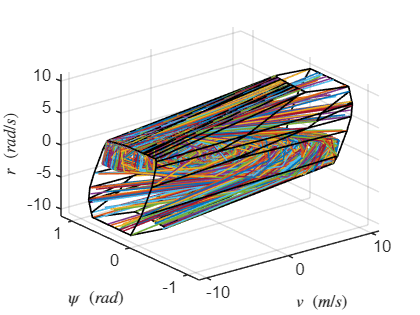

% Define paper column width for IEEE double-column format (approximately 3.5 inches / 8.89 cm)
column_width = 3.5; % Single column width in inches
half_column_width = column_width / 2; % Half column width

% Define font size (10 for IEEE)
font_size = 10;

% Projection of X3
Xf3 = [zeros(3,1), eye(3)] * Xf;

% Case 1: All vertices of X ⊗ Z with Constraints for Recursive Feasibility
figure;
set(gcf, 'Units', 'inches', 'Position', [1, 1, column_width, column_width * 0.75]);
plot(Xf3, 'wire', true);
hold on;
for m = 1:size(Xf.V,1)
    plot3(xData0{m}(2,:), xData0{m}(3,:), xData0{m}(4,:), 'LineWidth', 0.5);
    plot3(xData1{m}(2,:), xData1{m}(3,:), xData1{m}(4,:), 'LineWidth', 0.5);
end
ylim([-1.2, 1.2]); % Set y-axis range
zlabel('$r \ (rad/s)$', 'Interpreter', 'latex', 'FontSize', font_size);
ylabel('$\psi \ (rad)$', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$v \ (m/s)$', 'Interpreter', 'latex', 'FontSize', font_size);
set(gca, 'FontSize', font_size);
set(findall(gca, 'Type', 'text'), 'FontSize', font_size);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
exportgraphics(gcf, 'Figures/LK1.eps', 'ContentType', 'vector');

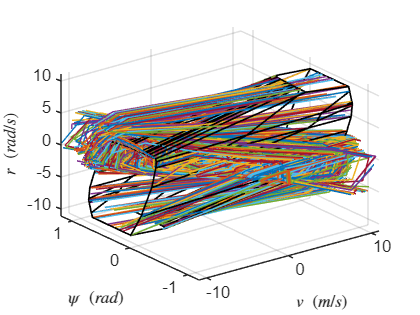


% Case 2: All vertices of X ⊗ Z without Constraints for Recursive Feasibility
figure;
set(gcf, 'Units', 'inches', 'Position', [1, 1, column_width, column_width * 0.75]);
plot(Xf3, 'wire', true);
hold on;
for m = 1:size(Xf.V,1)
    plot3(xData2{m}(2,:), xData2{m}(3,:), xData2{m}(4,:), 'LineWidth', 0.5);
    plot3(xData3{m}(2,:), xData3{m}(3,:), xData3{m}(4,:), 'LineWidth', 0.5);
end
ylim([-1.2, 1.2]); % Set y-axis range
zlabel('$r \ (rad/s)$', 'Interpreter', 'latex', 'FontSize', font_size);
ylabel('$\psi \ (rad)$', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$v \ (m/s)$', 'Interpreter', 'latex', 'FontSize', font_size);
set(gca, 'FontSize', font_size);
set(findall(gca, 'Type', 'text'), 'FontSize', font_size);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
exportgraphics(gcf, 'Figures/LK2.eps', 'ContentType', 'vector');

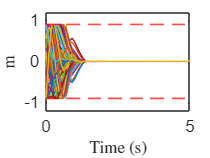


% Plot the 1st row (xData) for each case
figure;
set(gcf, 'Units', 'inches', 'Position', [1, 1, half_column_width, half_column_width * 0.75]);
for m = 1:size(Xf.V, 1)
    plot(0:T:Count*T, xData0{m}(1,:)); hold on;
    plot(0:T:Count*T, xData1{m}(1,:)); hold on;
end
yline(0.9, 'r--', 'LineWidth', 1); 
yline(-0.9, 'r--', 'LineWidth', 1); 
ylim([-1.2, 1.2]);
xlim([0, 5]); 
ylabel('$\mathrm{m}$', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$\mathrm{Time~(s)}$', 'Interpreter', 'latex', 'FontSize', font_size);
set(gca, 'FontSize', font_size);
set(findall(gca, 'Type', 'text'), 'FontSize', font_size);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
exportgraphics(gcf, 'Figures/LK3.eps', 'ContentType', 'vector');

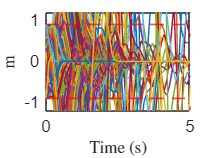


figure;
set(gcf, 'Units', 'inches', 'Position', [1, 1, half_column_width, half_column_width * 0.75]);
for m = 1:size(Xf.V, 1)
    plot(0:T:Count*T, xData2{m}(1,:)); hold on;
    plot(0:T:Count*T, xData3{m}(1,:)); hold on;
end
yline(0.9, 'r--', 'LineWidth', 1); 
yline(-0.9, 'r--', 'LineWidth', 1); 
ylim([-1.2, 1.2]);
xlim([0, 5]); 
ylabel('$\mathrm{m}$', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$\mathrm{Time~(s)}$', 'Interpreter', 'latex', 'FontSize', font_size);
set(gca, 'FontSize', font_size);
set(findall(gca, 'Type', 'text'), 'FontSize', font_size);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
exportgraphics(gcf, 'Figures/LK4.eps', 'ContentType', 'vector');

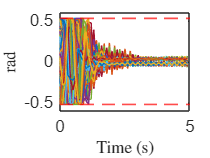


% Plot the 2nd row (uData) for each case
figure;
set(gcf, 'Units', 'inches', 'Position', [1, 1, half_column_width, half_column_width * 0.75]);
for m = 1:size(Xf.V, 1)
    plot(0:T:(Count-1)*T, uData0{m}); hold on;
    plot(0:T:(Count-1)*T, uData1{m}); hold on;
end
yline(um, 'r--', 'LineWidth', 1); 
yline(-um, 'r--', 'LineWidth', 1); 
ylim([-0.6, 0.6]); 
xlim([0, 5]); 
ylabel('$\mathrm{rad}$', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$\mathrm{Time~(s)}$', 'Interpreter', 'latex', 'FontSize', font_size);
set(gca, 'FontSize', font_size);
set(findall(gca, 'Type', 'text'), 'FontSize', font_size);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
exportgraphics(gcf, 'Figures/LK5.eps', 'ContentType', 'vector');

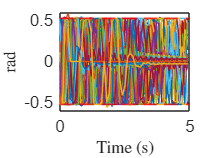


figure;
set(gcf, 'Units', 'inches', 'Position', [1, 1, half_column_width, half_column_width * 0.75]);
for m = 1:size(Xf.V, 1)
    plot(0:T:(Count-1)*T, uData2{m}); hold on;
    plot(0:T:(Count-1)*T, uData3{m}); hold on;
end
yline(um, 'r--', 'LineWidth', 1); 
yline(-um, 'r--', 'LineWidth', 1); 
ylim([-0.6, 0.6]); 
xlim([0, 5]); 
ylabel('$\mathrm{rad}$', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$\mathrm{Time~(s)}$', 'Interpreter', 'latex', 'FontSize', font_size);
set(gca, 'FontSize', font_size);
set(findall(gca, 'Type', 'text'), 'FontSize', font_size);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
exportgraphics(gcf, 'Figures/LK6.eps', 'ContentType', 'vector');

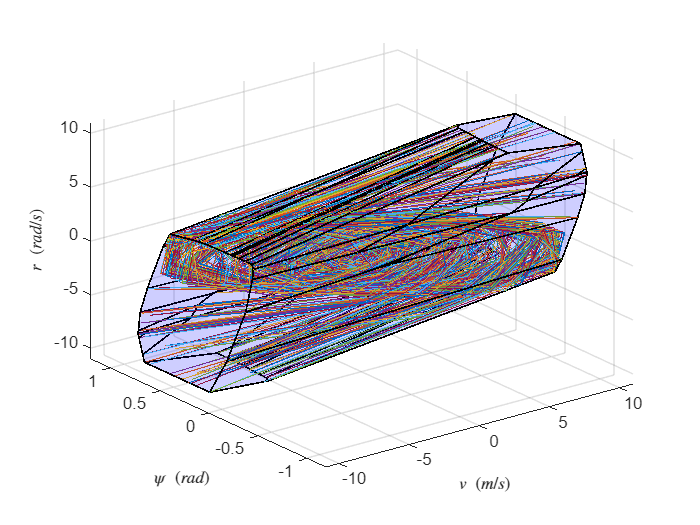

% Plot for visualizing the entire set of data
figure;
plot(Xf3, 'color', 'blue');
pHandles = findobj(gca, 'Type', 'patch');
set(pHandles, 'FaceAlpha', 0.1);
hold on;
for m = 1:size(Xf.V,1)
    plot3(xData0{m}(2,:), xData0{m}(3,:), xData0{m}(4,:), 'LineWidth', 0.1);
    plot3(xData1{m}(2,:), xData1{m}(3,:), xData1{m}(4,:), 'LineWidth', 0.1);
end
ylim([-1.2, 1.2]);
zlabel('$r \ (rad/s)$', 'Interpreter', 'latex', 'FontSize', font_size);
ylabel('$\psi \ (rad)$', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$v \ (m/s)$', 'Interpreter', 'latex', 'FontSize', font_size);
exportgraphics(gcf, 'Figures/LK1.jpg');

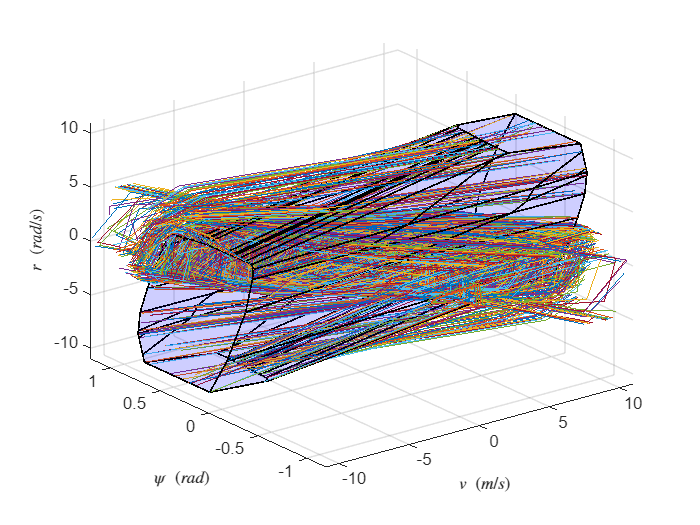


figure;
plot(Xf3, 'color', 'blue');
pHandles = findobj(gca, 'Type', 'patch');
set(pHandles, 'FaceAlpha', 0.1);
hold on;
for m = 1:size(Xf.V,1)
    plot3(xData2{m}(2,:), xData2{m}(3,:), xData2{m}(4,:), 'LineWidth', 0.5);
    plot3(xData3{m}(2,:), xData3{m}(3,:), xData3{m}(4,:), 'LineWidth', 0.5);
end
ylim([-1.2, 1.2]);
zlabel('$r \ (rad/s)$', 'Interpreter', 'latex', 'FontSize', font_size);
ylabel('$\psi \ (rad)$', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$v \ (m/s)$', 'Interpreter', 'latex', 'FontSize', font_size);
exportgraphics(gcf, 'Figures/LK2.jpg');